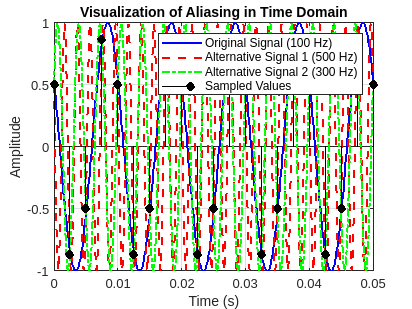

% Parameters
fs = 400;             % Sampling frequency (Hz)
f_original = 100;     % Original frequency (Hz)
f1 = 500;             % First alternative frequency (Hz)
f2 = 300;             % Second alternative frequency (Hz)
phi = pi/3;           % Phase shift
t_cont = 0:1e-4:0.05; % Continuous-time vector
n = 0:0.05*fs;        % Sample indices
Ts = 1/fs;            % Sampling interval

% Continuous-time signals
x_cont_original = cos(2*pi*f_original*t_cont + phi);
x_cont_f1 = cos(2*pi*f1*t_cont + phi);
x_cont_f2 = cos(2*pi*f2*t_cont - phi);

% Sampled signal
x_samples = cos(2*pi*(f_original/fs)*n + phi);

% Time vector for samples
t_samples = n*Ts;

% Plotting
figure;
plot(t_cont, x_cont_original, 'b', 'LineWidth', 1.5); hold on;
plot(t_cont, x_cont_f1, 'r--', 'LineWidth', 1.5);
plot(t_cont, x_cont_f2, 'g-.', 'LineWidth', 1.5);
stem(t_samples, x_samples, 'k', 'filled');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Signal (100 Hz)', 'Alternative Signal 1 (500 Hz)', 'Alternative Signal 2 (300 Hz)', 'Sampled Values');
title('Visualization of Aliasing in Time Domain');
grid on;